clear; 

% tab = table('Size',[0 4],'VariableTypes',["double","double","double","double"],'VariableNames',["Step","Kp","Tau","Td"]);

count = 1;
% Iterate through step sizes from -100 to 100
% for ii=cat(2,-20:1:-1,1:1:20)
ii = 10

ii = 10


% Set parameters like coolingflow, glucoseconc, and time
step_time = 250;
coolingflow_before = 440;
step = ii/100*coolingflow_before;
coolingflow_after = coolingflow_before + step;
glucoseconc_before = 275;
glucoseconc_after = glucoseconc_before;

load_system("CSTR_Bioreactor_2023.slx");
set_param("CSTR_Bioreactor_2023/mv_feedglucoseconc_step", "Time", int2str(step_time));
set_param("CSTR_Bioreactor_2023/mv_feedglucoseconc_step", "Before", int2str(glucoseconc_before));
set_param("CSTR_Bioreactor_2023/mv_feedglucoseconc_step", "After", int2str(glucoseconc_after));
set_param("CSTR_Bioreactor_2023/mv_coolingflow_step", "Time", int2str(step_time));
set_param("CSTR_Bioreactor_2023/mv_coolingflow_step", "Before", int2str(coolingflow_before));
set_param("CSTR_Bioreactor_2023/mv_coolingflow_step", "After", int2str(coolingflow_after));
simulate = sim("CSTR_Bioreactor_2023");

pv_ethanolconc = simulate.ScopeData{1}.Values;
pv_biotemp = simulate.ScopeData{2}.Values;
pv_ethanolconc_derivative = simulate.ScopeData{3}.Values;
pv_biotemp_derivative = simulate.ScopeData{4}.Values;
pv_ethanolconc_secondderivative = simulate.ScopeData{5}.Values;


pv_ethanolconc = getsampleusingtime(pv_ethanolconc,200,400);
pv_biotemp = getsampleusingtime(pv_biotemp,200,400);
pv_ethanolconc_derivative = getsampleusingtime(pv_ethanolconc_derivative,200,400);
pv_biotemp_derivative = getsampleusingtime(pv_biotemp_derivative,200,400);
pv_ethanolconc_secondderivative = getsampleusingtime(pv_ethanolconc_secondderivative,200,400);
[k_p, tau, T_d, vmax, dmax, tmax] = get_foptd(pv_ethanolconc, pv_ethanolconc_derivative, step_time, step);

% figure(1)
% fig1.fig = gcf
yyaxis left
plot(pv_ethanolconc)
hold on
ylabel("Concentration")

yyaxis right
plot(pv_ethanolconc_derivative, 'LineWidth', 1)
ylabel("Concentration Derivative")

yyaxis left
yline(pv_ethanolconc.Data(1), "--")
yline(pv_ethanolconc.Data(end), "--")

% xline(tmax, "--")


x = 200:1:320;
plot(x,dmax*(x-tmax)+vmax, "b")
xline(250+T_d, "--")
xline(250+T_d+tau, "--")
xline(250, "--")

xlim([240,320])
ylim([39.805,39.85])
title("", 'FontSize', 12)

Plot()

ans =   Plot with properties:

               BoxDim: [6 3]
              ShowBox: on
             FontName: 'Arial'
             FontSize: 12
            LineWidth: [1.5000 1.5000 1.5000 1.5000 1.5000 1.5000 1.5000]
            LineStyle: []
            LineCount: 7
              Markers: {'None'  'None'  'None'  'None'  'None'  'None'  'None'}
        MarkerSpacing: [5 5 5 5 5 5 5]
               Colors: []
            AxisColor: [0 0 0]
        AxisLineWidth: 1.5000
               XLabel: 'Time (seconds)'
               YLabel: 'Concentration'
               ZLabel: ''
                XTick: [240 250 260 270 280 290 300 310 320]
                YTick: [39.8100 39.8200 39.8300 39.8400 39.8500]
                ZTick: [-1 -0.5000 0]
           XTickLabel: {9×1 cell}
           YTickLabel: {5×1 cell}
           ZTickLabel: ''
           XMinorTick: on
           YMinorTick: on
           ZMinorTick: on
              TickDir: '

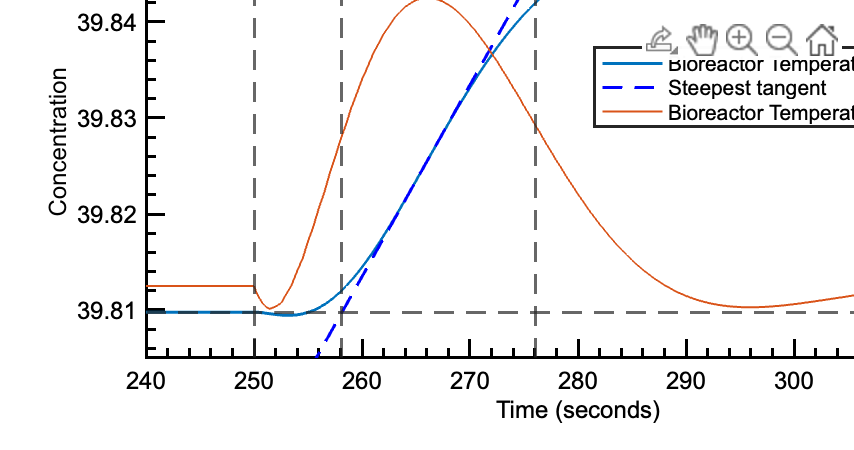




legend("Bioreactor Temperature", "", "","Steepest tangent", "","","","Bioreactor Temperature Derivative", 'Location', 'Best')
% title("Bioreactor Temperature")
% xlim([230,330])
% ylabel("Temperature")


% clf
% plot(pv_ethanolconc)
% hold on 


%plot(pv_biotemp)
%plot(pv_biotemp_derivative)



% title("Ethanol concentration steepest tangent")
% legend("Ethanol Concentration", "Steepest Gradient")
% ylabel("Concentration")


% tab(count,:) = {step, k_p, tau, T_d};
count = count+1;
exportgraphics(gcf,"figures/FOPTD_methods.pdf") 


% tab = table(pv_ethanolconc.Time, pv_ethanolconc.Data, pv_ethanolconc_derivative.Data,'VariableNames',["Time","EthanolConc","EthanolConcDerivative"])
% writetable(tab,'out/foptd_plot.xlsx')

function [k_p, tau, T_d, vmax, dmax, tmax] =  get_foptd(value, derivative, step_time, step)
medfilt_data = medfilt1(derivative.Data);
[dmax_abs, index] = max(abs(medfilt_data));
dmax = medfilt_data(index);
tmax = derivative.Time(index);
vmax = value.Data(index);
ss1_intercept = get_time(value.Data(1), vmax, dmax, tmax);
ss2_intercept = get_time(value.Data(end), vmax, dmax, tmax);
tau = ss2_intercept-ss1_intercept;
k_p = (value.Data(end)-value.Data(1))/(step);
T_d = ss1_intercept-step_time;
end

function time = get_time(y, vmax, dmax, tmax)
    time = (y-vmax)/dmax+tmax;
end
